## Finding Roots using Newton-Raphson method

The Newton–Raphson method is an iterative technique that uses the tangent line to estimate the root.

In this example, we will find the roots of $f(x) = x^2 - 4$

### Step 1: Define the function and its derivative

f = @(x) x.^2 - 4;
df = @(x) 2*x;

### Step 2: Plot the function

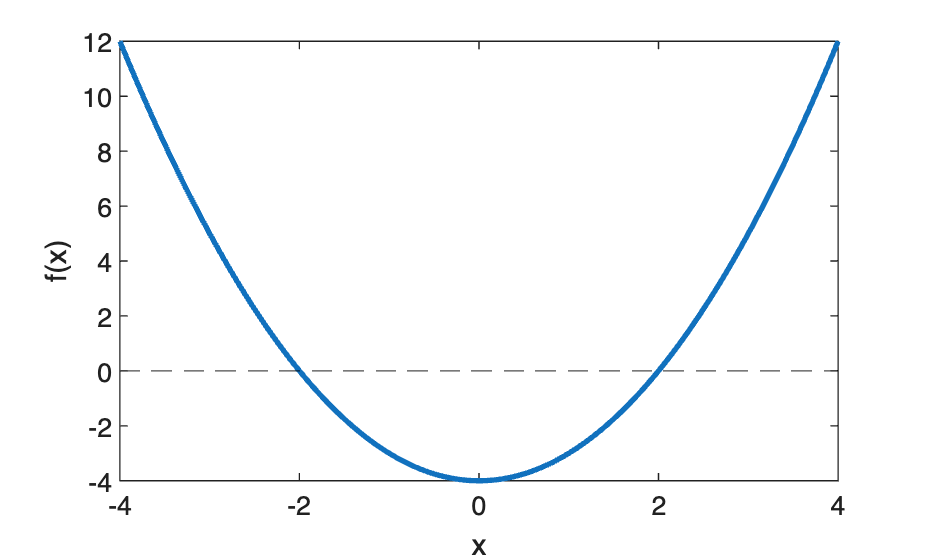

x = linspace(-4,4,500);

plot(x,f(x),'LineWidth',2)
hold on

yline(0,'k--')

xlabel('x')
ylabel('f(x)')
hold on

### Step 3: Choose an initial guess

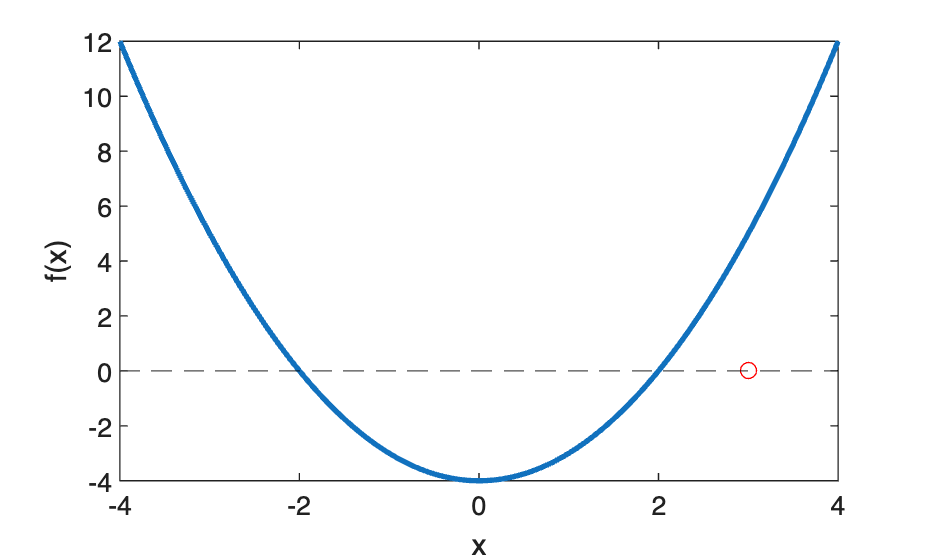

root_estimate = 3;

plot(root_estimate, 0, 'ro')

### Step 4: Apply the Newton–Raphson Formula


$$x_{n+1} = x_n - \frac{f(x_n}{f'(x_n)}$$
 

root_estimate = root_estimate - f(root_estimate)/df(root_estimate)

root_estimate = 2.1667

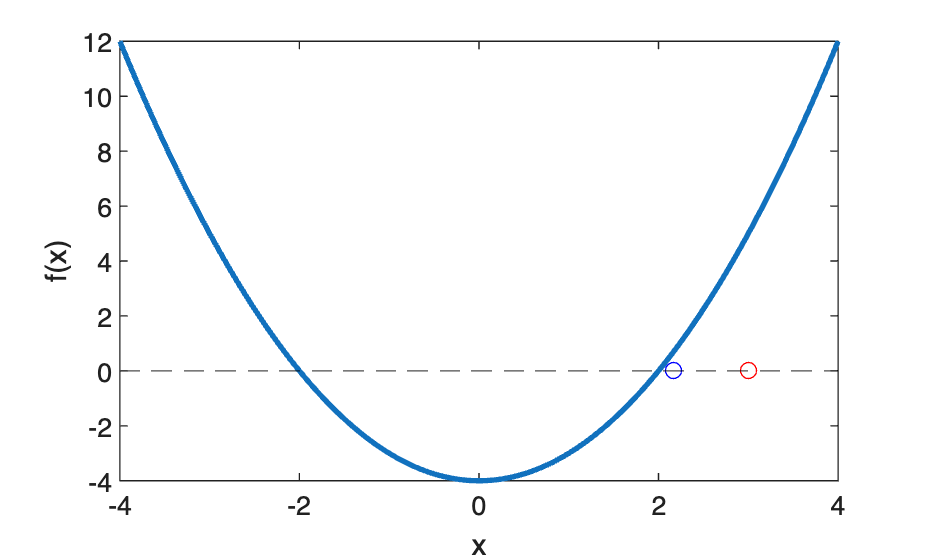

plot(root_estimate, 0, 'bo')

% What if we do this one more time?